ASD = load('/Users/domo/Documents/MATLAB/Graph_theory/Dissertation_code/Thresholding/ASD_fc_longitudinalv1_thresholded.mat');
tensor_ASD = ASD.tensor_ASDv1;
NT = load('/Users/domo/Documents/MATLAB/Graph_theory/Dissertation_code/Thresholding/NT_fc_longitudinalv1_thresholded.mat');
tensor_NT = NT.tensor_NTv1;

ASD_fc = tensor_ASD(:,:,:,66);
NT_fc = tensor_NT(:,:,:,66);

%spot check
nnz(ASD_fc(:,:,18))/(96^2)

ans = 0.3500

nnz(NT_fc(:,:,22))/(96^2)

ans = 0.3500


sum(diag(NT_fc(:,:,5)))

ans = 0

sum(diag(ASD_fc(:,:,13)))

ans = 0

ASD = [10001, 10002, 10003, 10004, 10005, 10008, 10010, 10020, 10021, 10050, 10059, 10061, 10069, 10077, 10079, 10090, 10091, 10092, 10093, 10096,...
    10101, 10115, 10119, 10124, 11001, 11003, 11007, 11014, 11019, 11031, 11038, 11044, 11054, 11059, 11061];
NT = [10009, 10013, 10014, 10015, 10016, 10017, 10019, 10036, 10044, 10052, 10057, 10076, 10086, 10088, 10103, 10106, 10112, 10113, 11006,...
    11008, 11009, 11013, 11016, 11021, 11027, 11028, 11032, 11039, 11041, 11074];

% beta1s_ASD_table = readtable('/Users/domo/Documents/MATLAB/Data/beta1s_ASD.xlsx');
% beta1s_NT_table = readtable('/Users/domo/Documents/MATLAB/Data/beta1s_NT.xlsx');
% 
% beta1s_ASD = table2array(beta1s_ASD_table);
% beta1s_NT = table2array(beta1s_NT_table);

RM96 = readtable("/Users/domo/Documents/MATLAB/Data/RM96_labels.xlsx");

mod_NT = [];
cs_NT = [];

% beta1s_filt_NT = [];
% NT_filt = []; 
for i = 1:length(NT)
    % if ismember(NT(i),beta1s_NT(:,1))
        % ind = find(NT(i)==beta1s_NT(:,1));
        % NT_filt = [NT_filt; NT(i)];
        % beta1s_filt_NT = [beta1s_filt_NT; beta1s_NT(ind,:)];

        fc = NT_fc(:,:,i);
        [m,Q] = modularity_und(fc);
        mod_NT = [mod_NT, Q];
        cs_NT = [cs_NT, m];
    % end
end


mod_ASD = [];
cs_ASD = [];

% beta1s_filt_ASD = [];
% ASD_filt = [];

for i = 1:length(ASD)
    % if ismember(ASD(i),beta1s_ASD(:,1))
    %     ind = find(ASD(i)==beta1s_ASD(:,1));
    %     ASD_filt = [ASD_filt; ASD(i)];
    %     beta1s_filt_ASD = [beta1s_filt_ASD; beta1s_ASD(ind,:)];

        fc = ASD_fc(:,:,i);
        [m,Q] = modularity_und(fc);
        mod_ASD = [mod_ASD, Q];
        cs_ASD = [cs_ASD, m];
    % end
end

%difference in modularity score ebtween ASD and NT
[p_m, od_m, es_m] = permutationTest(mod_ASD,mod_NT,10000)

p_m = 0.5816

od_m = -0.0038

es_m = -0.1385

%permutation testing to compare community structure between groups
[viASD, miASD] = partition_distance(cs_ASD);
[viNT, miNT] = partition_distance(cs_NT);
within_ASD = mean(miASD,'all');
within_NT = mean(miNT,'all');
total_within = within_ASD+within_NT;
randomdifferences = zeros(1,10000);
for i = 1:10000
    allobservations = [cs_ASD,cs_NT];
    permtuation = randperm(size(allobservations,2));
    randSample1 = allobservations(:,permtuation(1:size(cs_ASD,2)));
    randSample2 = allobservations(:,permtuation(size(cs_ASD,2)+1:length(permtuation)));
    [viS1, miS1] = partition_distance(randSample1);
    [viS2, miS2] = partition_distance(randSample2);
    randomdifferences(i) = mean(miS1,'all')+mean(miS2,'all');
end
p = (length(find(abs(randomdifferences)>abs(total_within)))+1)/(10000+1)

p = 0.0110

p_nodes = zeros(96,1);
nASD_sm = zeros(96,96);
nNT_sm = zeros(96,96);
for i = 1:96
    bin_ASD = zeros(96,size(cs_ASD,2));
    bin_NT = zeros(96,size(cs_NT,2));
    for j = 1:size(cs_ASD,2)
        label = cs_ASD(i,j);
        bin_ASD(:,j) = cs_ASD(:,j)==label;
        nASD_sm(i,:) = nASD_sm(i,:)+bin_ASD(:,j)';
    end
    for k = 1:size(cs_NT,2)
        label = cs_NT(i,k);
        bin_NT(:,k) = cs_NT(:,k)==label;
        nNT_sm(i,:) = nNT_sm(i,:)+bin_NT(:,k)';
    end 
    R_ASD = corrcoef(bin_ASD);
    R_NT = corrcoef(bin_NT);
    R_od = mean(R_ASD,'all')+mean(R_NT,'all');
    randomdifferences = zeros(1,10000);
    for l = 1:10000
        allobservations = [bin_ASD,bin_NT];
        permtuation = randperm(size(allobservations,2));
        randSample1 = allobservations(:,permtuation(1:size(cs_ASD,2)));
        randSample2 = allobservations(:,permtuation(size(cs_ASD,2)+1:length(permtuation)));
        R_S1 = corrcoef(randSample1);
        R_S2 = corrcoef(randSample2);
        randomdifferences(l) = mean(R_S1,'all')+mean(R_S2,'all');
    end
    p_nodes(i,1) = (length(find(abs(randomdifferences)>abs(R_od)))+1)/(10000+1);
end


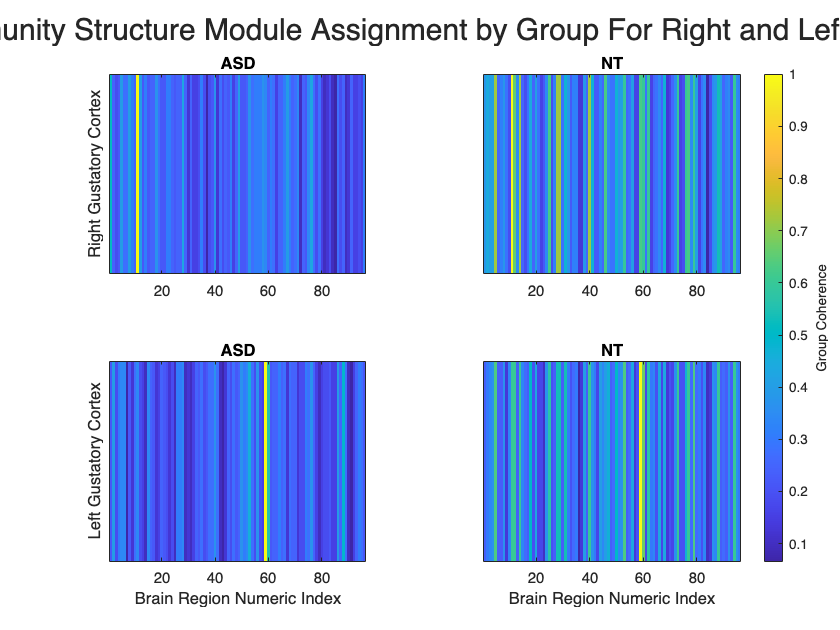

t = tiledlayout(2,2);
nexttile
imagesc(nASD_sm(11,:)/35)
title('ASD')
ylabel('Right Gustatory Cortex')
yticks([])

nexttile
imagesc(nNT_sm(11,:)/30)
title('NT')
yticks([])

nexttile
imagesc(nASD_sm(59,:)/35)
title('ASD')
xlabel('Brain Region Numeric Index')
ylabel('Left Gustatory Cortex')
yticks([])

nexttile
imagesc(nNT_sm(59,:)/30)
xlabel('Brain Region Numeric Index')
title('NT')
yticks([])

cb = colorbar;
cb.Layout.Tile = 'east';
cb.Label.String = 'Group Coherence';
title(t,'Functional Community Structure Module Assignment by Group For Right and Left Gustatory Cortex',fontsize=20)

%%load atlas info
RM96_coords = readtable('/Users/domo/Documents/MATLAB/Data/RM96_coords.xlsx');
RM96_labels = readtable('/Users/domo/Documents/MATLAB/Data/RM96_labels.xlsx');

%construct node file
nodes_table_ASD_gR = table();
nodes_table_ASD_gR.x = RM96_coords{:,'X'};
nodes_table_ASD_gR.y = RM96_coords{:,'Y'};
nodes_table_ASD_gR.z = RM96_coords{:,'Z'};
nodes_table_ASD_gR.color = nASD_sm(:,11)/35;
nodes_table_ASD_gR.size = ones(96,1);
nodes_table_ASD_gR.label = RM96_labels{:,'Labels'};


writetable(nodes_table_ASD_gR,'ASD_gR_fc_comstruct.txt','Delimiter','\t','WriteVariableNames',false)

%construct node file
nodes_table_NT_gR = table();
nodes_table_NT_gR.x = RM96_coords{:,'X'};
nodes_table_NT_gR.y = RM96_coords{:,'Y'};
nodes_table_NT_gR.z = RM96_coords{:,'Z'};
nodes_table_NT_gR.color = nNT_sm(:,11)/35;
nodes_table_NT_gR.size = ones(96,1);
nodes_table_NT_gR.label = RM96_labels{:,'Labels'};


writetable(nodes_table_NT_gR,'NT_gR_fc_comstruct.txt','Delimiter','\t','WriteVariableNames',false)

%construct node file
nodes_table_ASD_gL = table();
nodes_table_ASD_gL.x = RM96_coords{:,'X'};
nodes_table_ASD_gL.y = RM96_coords{:,'Y'};
nodes_table_ASD_gL.z = RM96_coords{:,'Z'};
nodes_table_ASD_gL.color = nASD_sm(:,59)/35;
nodes_table_ASD_gL.size = ones(96,1);
nodes_table_ASD_gL.label = RM96_labels{:,'Labels'};


writetable(nodes_table_ASD_gL,'ASD_gL_fc_comstruct.txt','Delimiter','\t','WriteVariableNames',false)

%construct node file
nodes_table_NT_gL = table();
nodes_table_NT_gL.x = RM96_coords{:,'X'};
nodes_table_NT_gL.y = RM96_coords{:,'Y'};
nodes_table_NT_gL.z = RM96_coords{:,'Z'};
nodes_table_NT_gL.color = nNT_sm(:,59)/35;
nodes_table_NT_gL.size = ones(96,1);
nodes_table_NT_gL.label = RM96_labels{:,'Labels'};


writetable(nodes_table_NT_gL,'NT_gL_fc_comstruct.txt','Delimiter','\t','WriteVariableNames',false)

func_Newman_table = readtable("/Users/domo/Documents/MATLAB/Data/RM96_labels.xlsx");
func_Newman_table.P_value = p_nodes

func_Newman_table = 96×2 table
        Labels          P_value  
    _______________    __________

    {'RM-TCpol_R' }        0.9758
    {'RM-TCs_R'   }       0.75062
    {'RM-Amyg_R'  }       0.56204
    {'RM-PFCoi_R' }       0.25247
    {'RM-IA_R'    }      0.079192
    {'RM-PFCom_R' }       0.15758
    {'RM-TCc_R'   }      0.077392
    {'RM-PFCol_R' }       0.34937
    {'RM-TCi_R'   }       0.20568
    {'RM-PHC_R'   }       0.45485
    {'MM82a-G_R'  }    0.00029997
    {'RM-PMCvl_R' }     0.0067993
    {'RM-VACv_R'  }       0.37616
    {'RM-Ip_R'    }      0.069893
    {'RM-PFCpol_R'}      0.020898
    {'RM-HC_R'    }       0.29947


writetable(func_Newman_table,'func_Newman_nodal_results.xlsx')